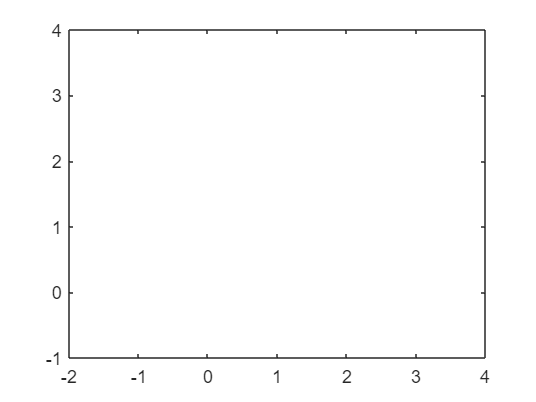


clear
clc

f1 = @(x) -x; 
f2 = @(x)  x;
[dist, x] = meshgrid([0 .01 .1 .5 1], -2:.001:4);
foo = blend(f1, f2, 1, dist);
plot(x, foo(x))




            C_Z0 = 0.35;
            C_Za = 0.11;
            C_D0 = 0.01;
            C_Da = 0.2;
            
            c_z = C_Z0 + C_Za * alpha; 
            c_x = C_D0 + C_Da * alpha * alpha; 

            drag_cal = q_bar * obj.WingSurfaceArea * 0.03;
            lateral_cal = q_bar * obj.WingSurfaceArea * c_y;
            lift_cal = q_bar * obj.WingSurfaceArea * 0.35;
                    
            air_speed_norm = norm(obj.State.Velocity);

            if air_speed_norm < obj.blending_air_speed

            drag = 0;
            lateral = 0;
            lift = 0;

            elseif air_speed_norm >= obj.blending_air_speed && air_speed_norm < obj.Transition_air_speed

            ratio = (air_speed_norm - obj.blending_air_speed) / (obj.Transition_air_speed - obj.blending_air_speed);

            drag = drag_cal * ratio;
            lateral = lateral_cal  * ratio;
            lift = lift_cal * ratio;

            elseif air_speed_norm >= obj.Transition_air_speed
           
            drag = drag_cal;
            lateral = lateral_cal;
            lift = lift_cal;  

            end



function foo = blend(f1,f2,location,distance)
% BLEND  Uses hyperbolic tangent (tanh) to smoothly blend two functions or
% smoothly combine a piecewise function into a single function handle.
% 
%   foo = BLEND(f1,f2,LOC,DIST) returns function handle foo which, when
%   evaluated, will return a smooth blend between functions provided in handles
%   f1 and f2.
% 
%   The blend is centered around LOC, and most of the smooth blend happens in
%   the region LOC +/- DIST such that F will have value ca. 0.88*f1(x) + 0.12*f2
%   at LOC - DIST and 0.12*f1(x) + 0.88*f2(x) at LOC + DIST. Default LOC = 0.
% 
%   For a pure piecewise function, set the blend distance DIST to zero. F will
%   evaluate to NaN at x = LOC. To avoid evaluating to NaN at x = LOC, use eps
%   instead of zero. Default DIST = 0.
% 
%   f1 and/or f2 may be numeric constants instead of function handles.
% 
%   Example 1: Make a single function handle for a piecewise function (no
%   smoothing).
%     foo = blend(@sin, 1, pi/2);
%     ezplot(foo, [0 pi])
% 
%   Example 2: Make a smooth function from a discontinuous piecewise function
%   and use vectorization to illustrate the effect of different blending
%   distances.
%     f1 = @(x) -x; 
%     f2 = @(x)  x;
%     [dist, x] = meshgrid([0 .01 .1 .5 1], -2:.001:4);
%     foo = blend(f1, f2, 1, dist);
%     plot(x, foo(x))
% 
%   See also tanh, piecewise.
% 
%   foo = BLEND(f1,f2,LOC,DIST)
% Copyright 2016 Sky Sartorius
% Contact: www.mathworks.com/matlabcentral/fileexchange/authors/101715
if nargin < 4
    distance = 0;
end
if nargin < 3 || isempty(location)
    location = 0;
end
validateattributes(location, {'numeric','DimVar'}, {},...
    'blend', 'blending center location', 3);
validateattributes(distance, {'numeric','DimVar'}, {'nonnegative'},...
    'blend', 'blending distance', 4);
if isnumeric(f1)
    f1 = @(~) f1;
end
if isnumeric(f2)
    f2 = @(~) f2;
end
blf = @(x) tanh((x-location)./distance)/2;
foo = @(x) (1/2 - blf(x)).*f1(x) + (1/2 + blf(x)).*f2(x);
end


